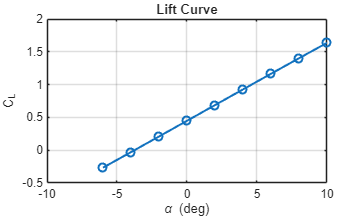

clc
clear

filename = 'polar_output.txt';   % your AVL output file
txt = fileread(filename);

% Extract AoA
alpha = regexp(txt,'Alpha\s*=\s*([-+]?\d*\.?\d+)','tokens');
alpha = cellfun(@(x) str2double(x{1}), alpha);

% Extract CL values
CL = regexp(txt,'CLtot\s*=\s*([-+]?\d*\.?\d+)','tokens');
CL = cellfun(@(x) str2double(x{1}), CL);

% Extract CD values
CD = regexp(txt,'CDtot\s*=\s*([-+]?\d*\.?\d+)','tokens');
CD = cellfun(@(x) str2double(x{1}), CD);

% Make sure they align
n = min([length(alpha), length(CL), length(CD)]);
alpha = alpha(1:n);
CL = CL(1:n);
CD = CD(1:n);

% Remove duplicates (AVL sometimes repeats last case)
[alpha, uniqueIdx] = unique(alpha);
CL = CL(uniqueIdx);
CD = CD(uniqueIdx);

%% Plot Lift Curve
figure
plot(alpha, CL, 'o-','LineWidth',1.5)
xlabel('\alpha (deg)')
ylabel('C_L')
grid on
title('Lift Curve')

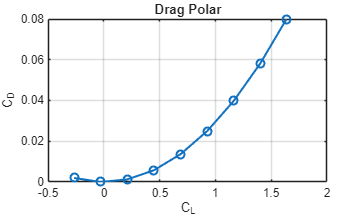


%% Plot Drag Polar
figure
plot(CL, CD, 'o-','LineWidth',1.5)
xlabel('C_L')
ylabel('C_D')
grid on
title('Drag Polar')